# Homework 7

William Watkins in collaboration with Roland Ilyes, Jacob Weiner

18 Oct

## Question 1

Set up the workspace

clear
close
clc

Declare globals, constants, and conversions

global E1 theta0

Constants.g = 9.81; % [m/s^2]

Conv.FtToM          = 0.3048; % ft to m
Conv.LbToN          = 4.44822; % lb to N
Conv.SlugFt2ToKgM2  = 1.35581795; % slug*ft^2 to kg*m^2
Conv.DegToRad       = pi / 180; % deg to rad

Values from table E.1, for Case 2.

E1.Altitude = 20000         * Conv.FtToM;         % Altitude of 747 in meters
E1.M        = 0.5;                                % Mach number
E1.Velocity = 518           * Conv.FtToM;         % Velocity in [m/s]
E1.Weight   = 6.366 * 10^5  * Conv.LbToN;         % Weight of the 747 in Newtons
E1.Ix       = 1.82  * 10^7  * Conv.SlugFt2ToKgM2; % Moment of Inertia about x axis
E1.Iy       = 3.31  * 10^7  * Conv.SlugFt2ToKgM2; % Moment of Inertia about y axis
E1.Iz       = 4.97  * 10^7  * Conv.SlugFt2ToKgM2; % Moment of Inertia about z axis
E1.Izx      = 9.70  * 10^5  * Conv.SlugFt2ToKgM2; % Product of Inertia about z and x axes
E1.Xi       = -6.8          * Conv.DegToRad;      % Angle between stability and body frames
E1.CD       = 0.040;                              % Coefficient of Drag
E1.m        = E1.Weight     / Constants.g;        % Mass of the 747

Values from table E.3, longitudinal, all converted to SI units.

E3.X.u      = -4.883 * 10^1 * Conv.LbToN / Conv.FtToM;  % [N * s / m]
E3.X.w      = 1.546  * 10^3 * Conv.LbToN / Conv.FtToM;  % [N * s / m]
E3.X.q      = 0             * Conv.LbToN;               % [N * s / rad]
E3.X.wDot   = 0             * Conv.LbToN / Conv.FtToM;  % [N * s^2 / m]
E3.X.deltae = 3.994  * 10^4 * Conv.LbToN;               % [N / rad]

E3.Z.u      = -1.342 * 10^3 * Conv.LbToN / Conv.FtToM;  % [N * s / m]
E3.Z.w      = -8.561 * 10^3 * Conv.LbToN / Conv.FtToM;  % [N * s / m]
E3.Z.q      = -1.263 * 10^5 * Conv.LbToN;               % [N * s / rad]
E3.Z.wDot   = 3.104  * 10^2 * Conv.LbToN / Conv.FtToM;  % [N * s^2 / m]
E3.Z.deltae = -3.341 * 10^5 * Conv.LbToN;               % [N / rad]

E3.M.u      = 8.176  * 10^3 * Conv.LbToN;               % [N * s]
E3.M.w      = -5.627 * 10^4 * Conv.LbToN;               % [N * s]
E3.M.q      = -1.394 * 10^7 * Conv.LbToN * Conv.FtToM;  % [N * m * s / rad]
E3.M.wDot   = -4.138 * 10^3 * Conv.LbToN;               % [N * s^2]
E3.M.deltae = -3.608 * 10^7 * Conv.LbToN * Conv.FtToM;  % [N * m / rad]

disp(E3.X)

         u: -712.6200
         w: 2.2562e+04
         q: 0
      wDot: 0
    deltae: 1.7766e+05



disp(E3.Z)

         u: -1.9585e+04
         w: -1.2494e+05
         q: -5.6181e+05
      wDot: 4.5299e+03
    deltae: -1.4862e+06



disp(E3.M)

         u: 3.6369e+04
         w: -2.5030e+05
         q: -1.8900e+07
      wDot: -1.8407e+04
    deltae: -4.8918e+07



## Question 2

Conversions to stability frame using coordinate rotations in eqn (B.12, 6).

XuPrime = E3.X.u * cos(E1.Xi)^2 - (E3.X.w + E3.Z.u) ...
    * sin(E1.Xi) * cos(E1.Xi) + E3.Z.w * sin(E1.Xi)^2;
XwPrime = E3.X.w * cos(E1.Xi)^2 + (E3.X.u - E3.Z.w) ...
    * sin(E1.Xi) * cos(E1.Xi) - E3.Z.u * sin(E1.Xi)^2;
XqPrime = E3.X.q * cos(E1.Xi) - E3.Z.q * sin(E1.Xi);
XuDotPrime = E3.Z.wDot * sin(E1.Xi)^2;
XwDotPrime = -E3.Z.wDot * sin(E1.Xi) * cos(E1.Xi);

ZuPrime = E3.Z.u * cos(E1.Xi)^2 - (E3.Z.w - E3.X.u) ...
    * sin(E1.Xi) * cos(E1.Xi) - E3.X.w * sin(E1.Xi)^2;
ZwPrime = E3.Z.w * cos(E1.Xi)^2 + (E3.Z.u + E3.X.w) ...
    * sin(E1.Xi) * cos(E1.Xi) + E3.X.u * sin(E1.Xi)^2;
ZqPrime = E3.Z.q * cos(E1.Xi) + E3.X.q * sin(E1.Xi);
ZuDotPrime = -E3.Z.wDot * sin(E1.Xi) * cos(E1.Xi);
ZwDotPrime = E3.Z.wDot * cos(E1.Xi)^2;

MuPrime = E3.M.u * cos(E1.Xi) - E3.M.w * sin(E1.Xi);
MwPrime = E3.M.w * cos(E1.Xi) + E3.M.u * sin(E1.Xi);
MqPrime = E3.M.q;
MuDotPrime = -E3.M.wDot * sin(E1.Xi);
MwDotPrime = E3.M.wDot * cos(E1.Xi);

## Question 3

Using the Stability frames constructed above, the 4x4 A matrix from eqn (4.9,18) for the linearized longitudinal dynamics is created.

A = zeros(4,4);
theta0 = 0;

A(1,1) = XuPrime / E1.m;
A(1,2) = XwPrime / E1.m;
A(1,3) = 0;
A(1,4) = -Constants.g * cos(theta0);

A(2,1) = ZuPrime / (E1.m - ZwDotPrime);
A(2,2) = ZwPrime / (E1.m - ZwDotPrime);
A(2,3) = (ZqPrime + E1.m * E1.Velocity) / (E1.m - ZwDotPrime);
A(2,4) = (-E1.Weight * sin(theta0)) / (E1.m - ZwDotPrime);

A(3,1) = E1.Iy ^ (-1) * (MuPrime + ((MwDotPrime * ZuPrime) / (E1.m - ZwDotPrime)));
A(3,2) = E1.Iy ^ (-1) * (MwPrime + ((MwDotPrime * ZwPrime) / (E1.m - ZwDotPrime)));
A(3,3) = E1.Iy ^ (-1) * (MqPrime + (MwDotPrime * (ZqPrime + E1.m * E1.Velocity) ...
    / (E1.m - ZwDotPrime)));
A(3,4) = -(MwDotPrime * E1.Weight * sin(theta0)) / (E1.Iy * (E1.m - ZwDotPrime));

A(4,1) = 0;
A(4,2) = 0;
A(4,3) = 1;
A(4,4) = 0;

## Question 4

The eigenvalues of the A matrix constructed above are found, plotted against a real vs imaginary plot, then the response time of each eigenvalue is plotted.

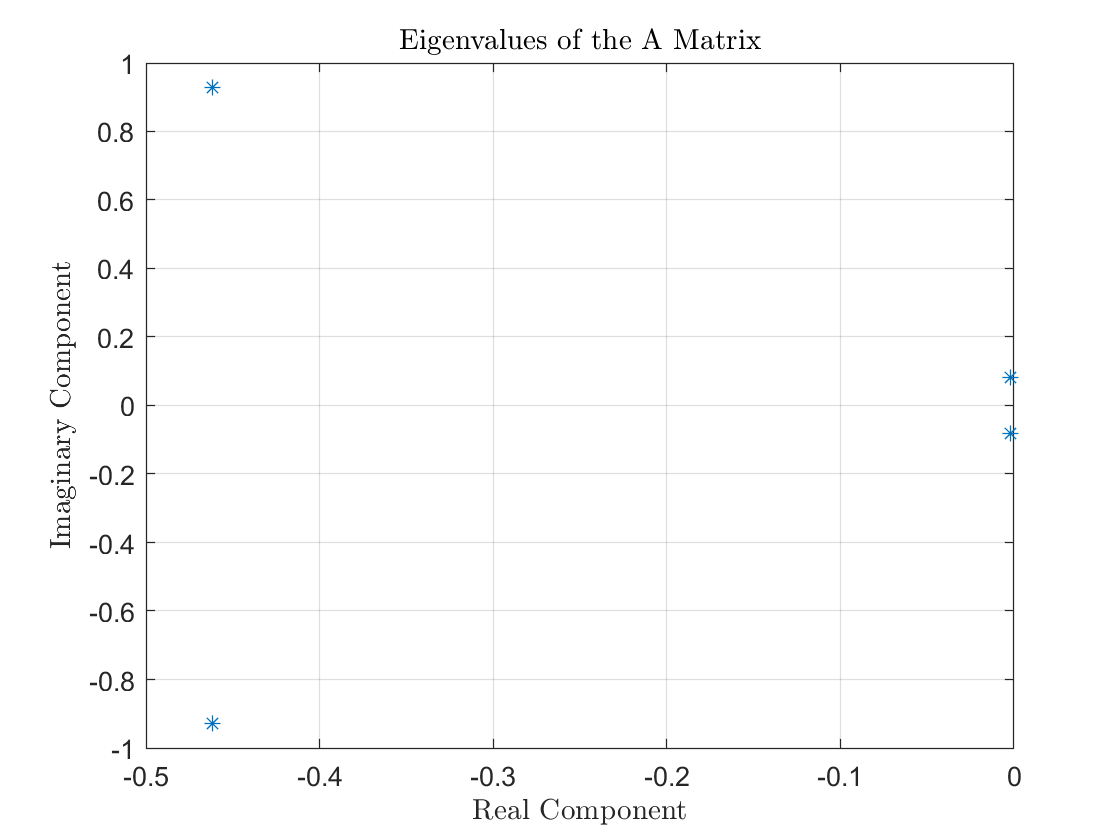

[V, D] = eig(A); % returns a vector containing the eigenvectors, and a vector

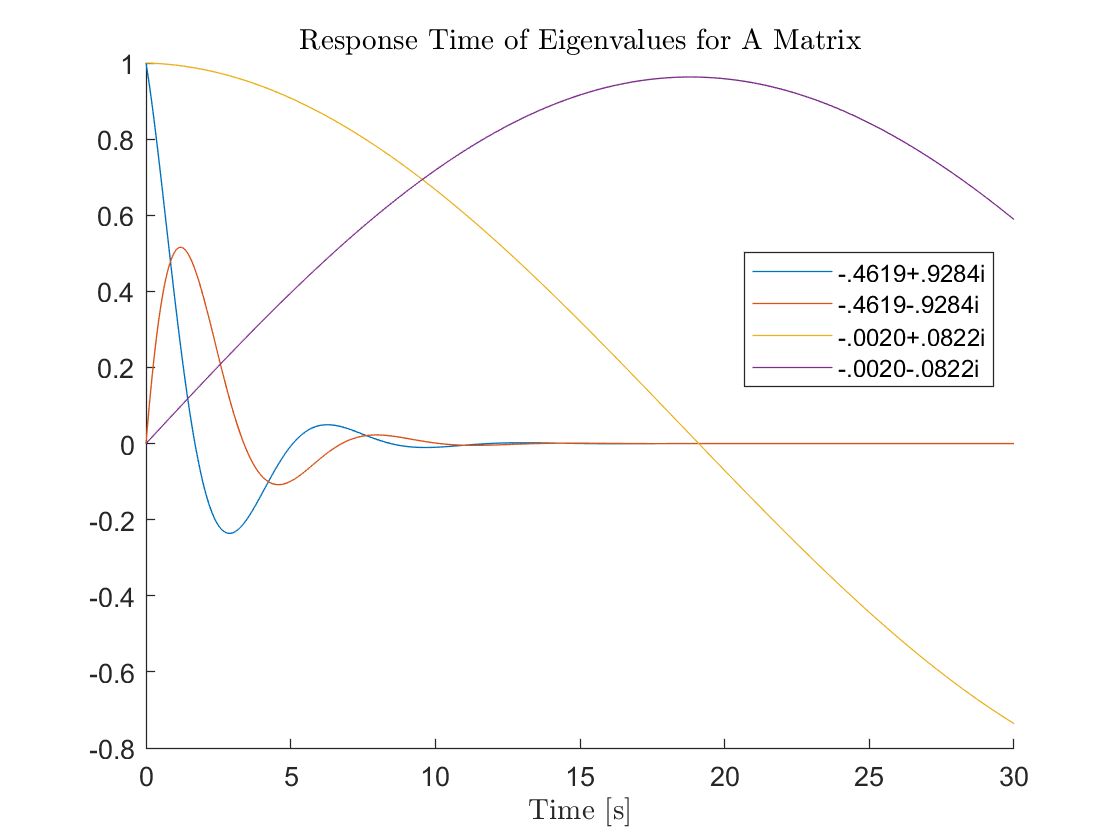

% containing the eigenvalues along the diagonal
D = diag(D); % Eigenvalues are extracted from the diagonal

figure()
plot(D,'*')
hold on
title('Eigenvalues of the A Matrix')
grid on
xlabel('Real Component')
ylabel('Imaginary Component')
hold off

t = linspace(0,30,3000);
figure()
hold on

y1 = exp(real(D(1) .* t)) .* cos(imag(D(1) .* t)); % Short Period, positive imaginary
y2 = exp(real(D(1) .* t)) .* sin(imag(D(1) .* t)); % Short Period, negative imaginary
y3 = exp(real(D(3) .* t)) .* cos(imag(D(3) .* t)); % Phugoid, pos imaginary
y4 = exp(real(D(3) .* t)) .* sin(imag(D(3) .* t)); % Phugoid, neg imaginary
plot(t, y1);
plot(t, y2);
plot(t, y3);
plot(t, y4);
legend('-.4619+.9284i','-.4619-.9284i','-.0020+.0822i','-.0020-.0822i','Location','best')
title('Response Time of Eigenvalues for A Matrix')
xlabel('Time [s]')
hold off
t = 0;

xi_sp = real(D(1)); % Real part of the short period eigenvalues
eta_sp = imag(D(1)); % Imaginary part of the short period eigenvalues
zeta_sp = sqrt(1 / (1 + (eta_sp / xi_sp)^2) ); 
% Modal damping ratio for short period eigenvalues
omega_sp = -xi_sp / zeta_sp; 

   0.0301 + 0.0099i
   0.9995 + 0.0000i
  -0.0001 + 0.0059i
   0.0051 - 0.0024i



% Modal natural frequency for short period eigenvalues
period_sp = (2*pi) / (omega_sp * sqrt(1 - zeta_sp^2) ); 

   0.0301 - 0.0099i
   0.9995 + 0.0000i
  -0.0001 - 0.0059i
   0.0051 + 0.0024i



% Period for short period eigenvalues


   0.9996 + 0.0000i
  -0.0264 - 0.0074i
   0.0007 - 0.0000i
  -0.0006 - 0.0084i



xi_ph = real(D(3)); % Real part of the phugoid eigenvalues
eta_ph = imag(D(3)); % Imaginary part of the phugoid eigenvalues

   0.9996 + 0.0000i
  -0.0264 + 0.0074i
   0.0007 + 0.0000i
  -0.0006 + 0.0084i



zeta_ph = sqrt(1 / (1 + (eta_ph / xi_ph)^2) ); 
% Modal damping ratio for phugoid
omega_ph = -xi_ph / zeta_ph; % Modal natural frequency for phugoid
period_ph = (2*pi) / (omega_ph * sqrt(1 - zeta_ph^2) ); % Period for phugoid

Short Period mode is given by -0.4619 +/- 0.9284i, with a modal damping ratio of $\zeta = 0.4454$, a modal natural frequency of $\omega_n = 1.037$ $Hz$, and an oscillation period of $T = 6.768$ seconds.  The Short Period mode with positive imaginary part has the following eigenvector:

disp(V(:,1))

While the eigenvector corresponding to the negative imaginary part is:

disp(V(:,2))

The Phugoid mode is given by -0.0020 +/- 0.0822i, with a modal damping ratio of $\zeta = 0.0240$, a modal natural frequency of $\omega_n = 0.0822$ $Hz$, and an oscillation period of $T = 76.42$ seconds.  The Phugoid mode with positive imaginary part has the following eigenvector:

disp(V(:,3))

While the eigenvector corresponding to the negative imaginary part is:

disp(V(:,4))

## Question 5

The short period approximation is given by the following:

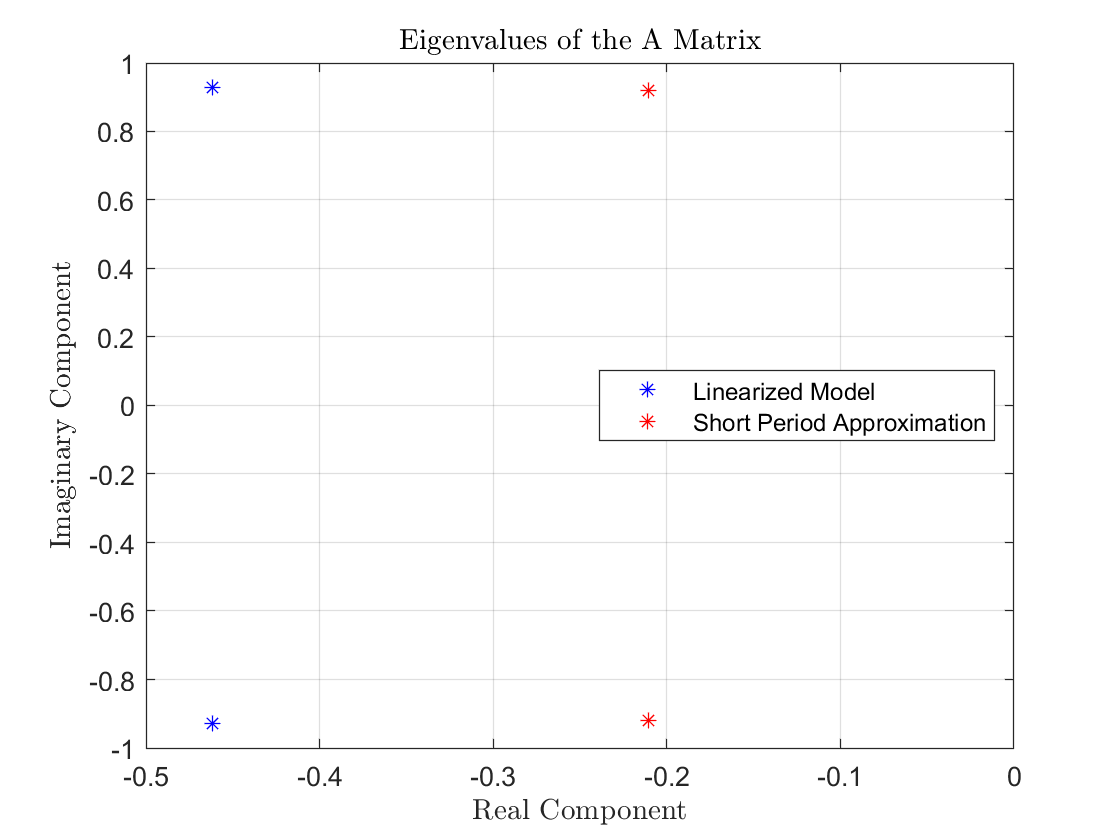

Q = [MqPrime/E1.Iy, MwPrime*E1.Velocity/E1.Iy;
     1,             0]; % New A matrix for short period approx
[V5, D5] = eig(Q); 
D5 = diag(D5);

figure() % Plotting the approximate and actual short period eigenvalues against each other
plot(D(1:2), 'b*')
hold on
plot(D5, 'r*')
title('Eigenvalues of the A Matrix')

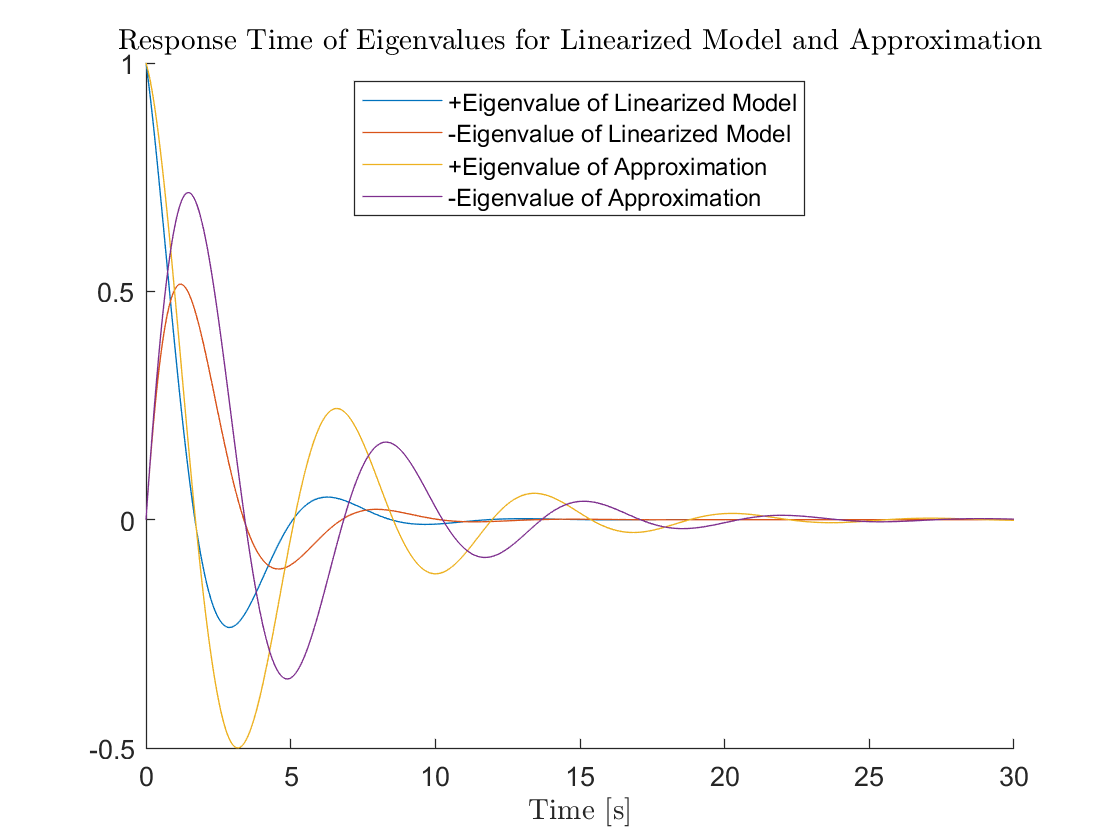

grid on
legend('Linearized Model','Short Period Approximation','Location','best')
xlabel('Real Component')
ylabel('Imaginary Component')
xlim([-0.5 0])

hold off

t = linspace(0,30,3000);
figure();
hold on
y1 = exp(real(D(1) .* t)) .* cos(imag(D(1) .* t)); % Short Period actual, pos imag
y2 = exp(real(D(1) .* t)) .* sin(imag(D(1) .* t)); % Short Period actual, neg imag
y3 = exp(real(D5(1) .* t)) .* cos(imag(D5(1) .* t)); % Short Period approx, pos imag
y4 = exp(real(D5(1) .* t)) .* sin(imag(D5(1) .* t)); % Short Period approx, neg imag
plot(t, y1);
plot(t, y2);

plot(t, y3);
plot(t, y4);
legend('+Eigenvalue of Linearized Model','-Eigenvalue of Linearized Model',...
    '+Eigenvalue of Approximation','-Eigenvalue of Approximation','Location','best')
title('Response Time of Eigenvalues for Linearized Model and Approximation')
xlabel('Time [s]')
hold off
t = 0;

We can see the short period approximation's eigenvalues do not closely approximate the actual short period eigenvalues.  The real component is approximately half of the actual eigenvalues, whereas the imaginary parts are within +/- 0.02.  From the response time graph, we can see that the approximated eigenvalues have a slightly longer period than the real eigenvalues, and they also undershoot compared to the actual eigenvalues.

period_lan = pi * sqrt(2) * E1.Velocity / Constants.g; % Lanchester Appox

Using the Lanchester Approximation in the book, we arrive at a period of 71.51 seconds.  This is remarkably close to the actual value for the period of the phugoid mode of 76.42 seconds.

## Question 6

### Part a

Simulation of the linearized longitudinal dynamics to confirm that the trim state is in equilibrium.

Setting the initial values for undisturbed flight.

initialDeltauE      = 0; % Change in horizontal velocity
initialDeltavE      = 0; % Change in vertical velocity
initialDeltaq       = 0; % 
initialDeltaTheta   = 0;
initialDeltaxE      = 0;
initialDeltazE      = E1.Altitude;

tSpan               = 0:2000;
initial             = [initialDeltauE;
                       initialDeltavE;
                       initialDeltaq;
                       initialDeltaTheta;
                       initialDeltaxE;
                       initialDeltazE]; % Created this for a "reset" button!
initialState        = initial; % Set our actual initial state equal to what we want

Plug into the ODE45 function, and then plot the results.

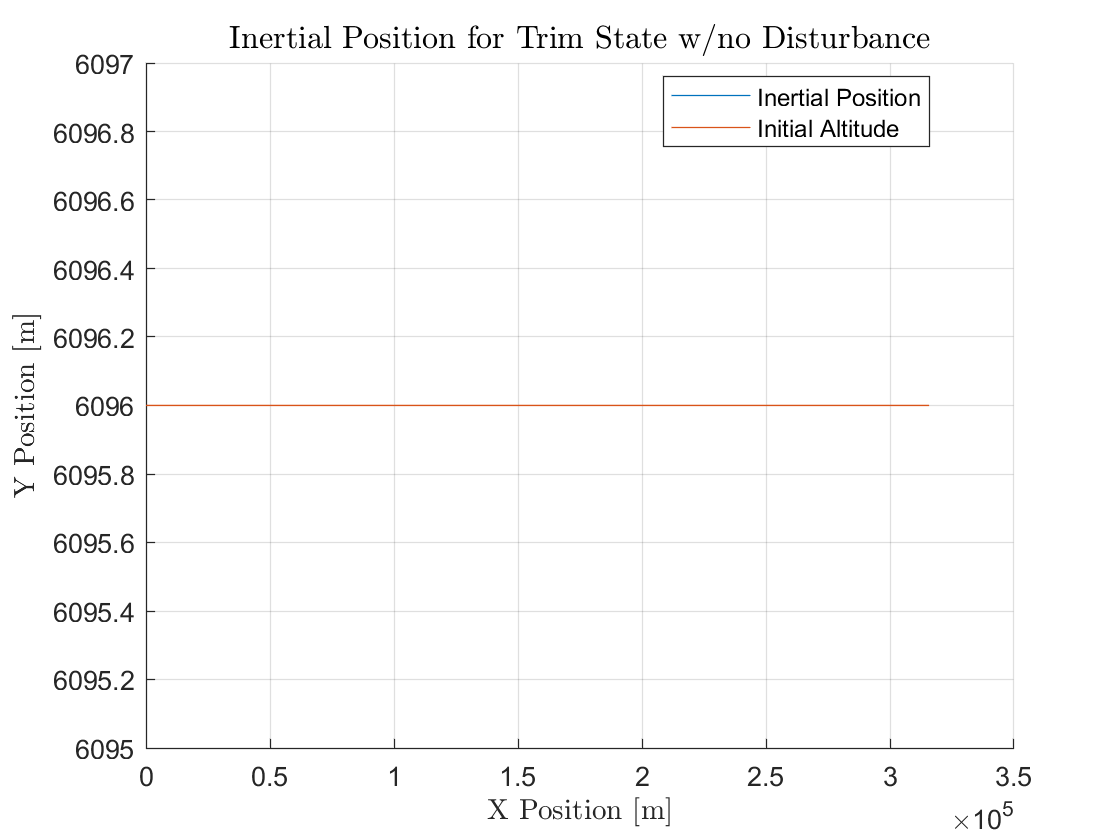

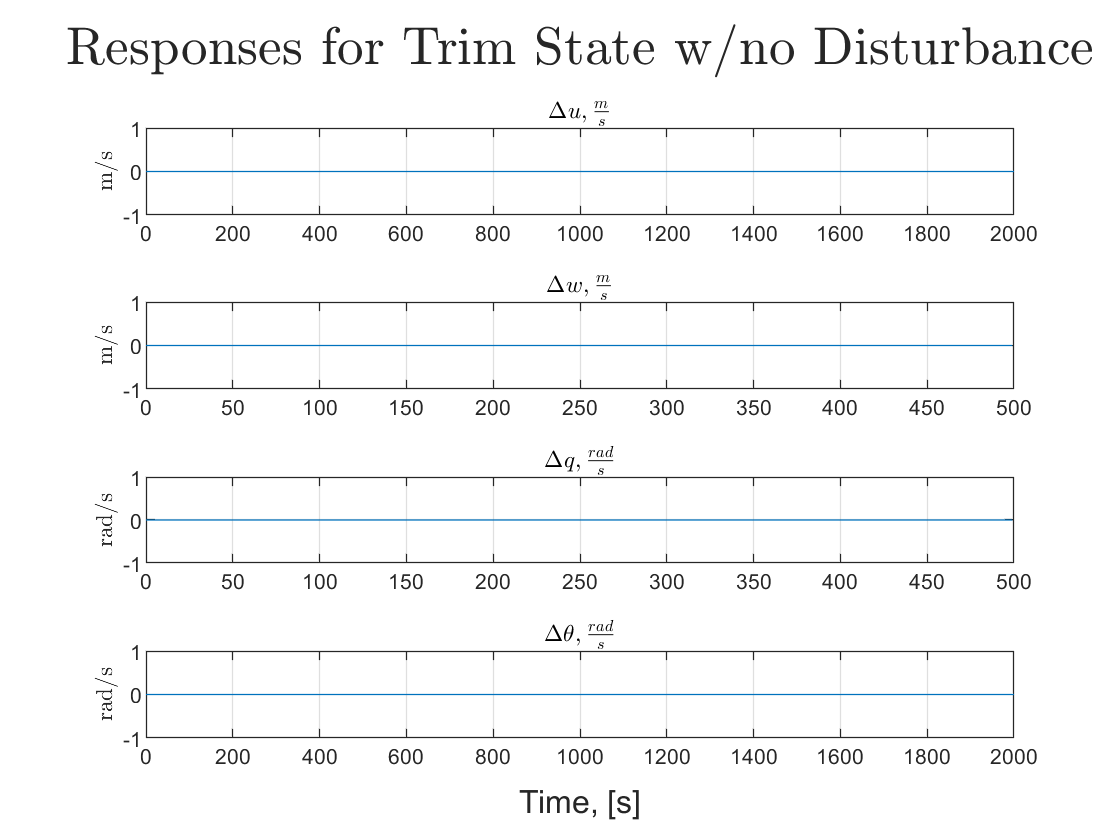

[t, y] = ode45(@(t, y) AirplaneLinearized(t, y, A), tSpan, initialState);
 
plutter(t, y, 'Trim State w/no Disturbance')

t = 0;
y = 0; % reset so that we don't have to change variable names

### Part b.i

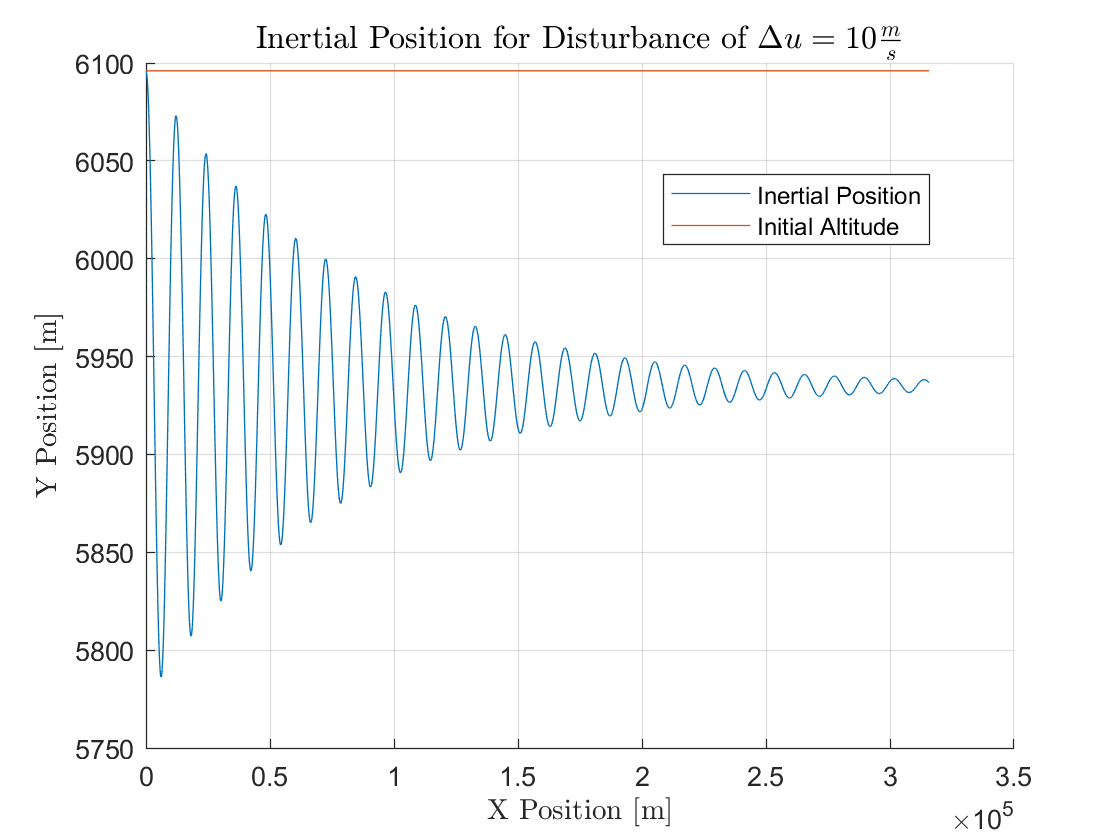

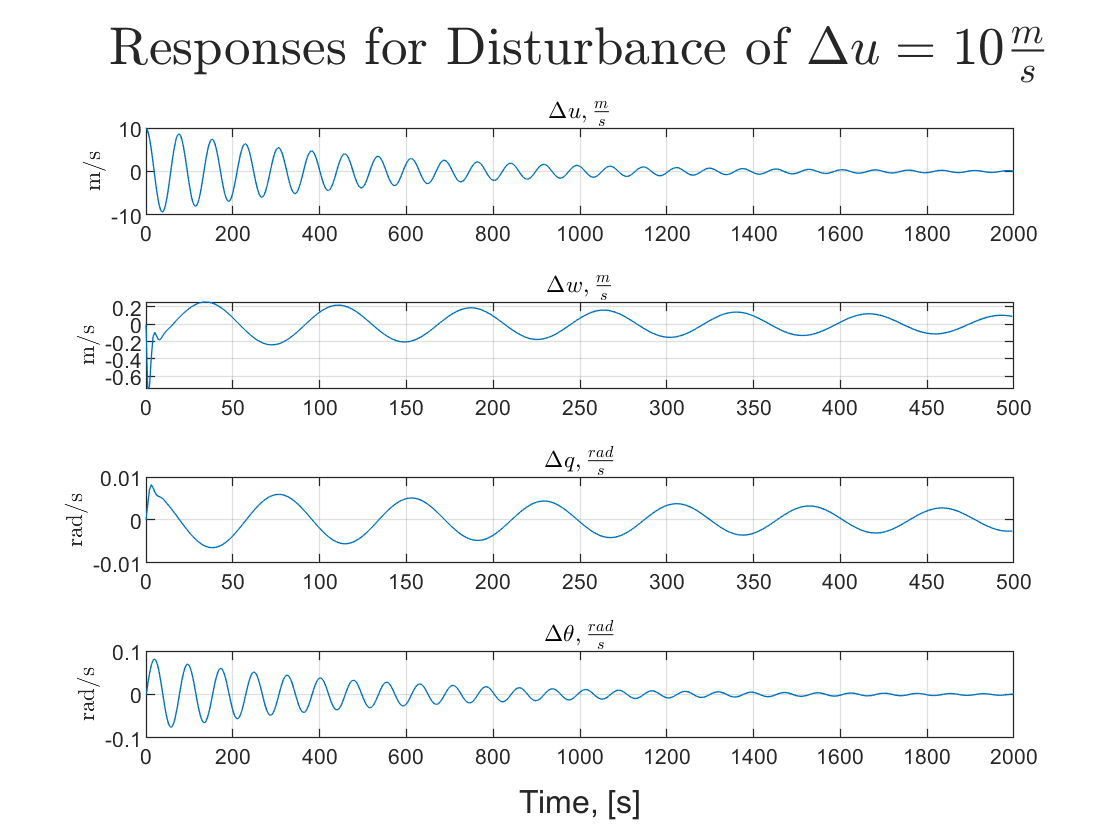

initialState(1) = 10; % Initial Delta u deviation of 10 [m/s]
[t, y] = ode45(@(t, y) AirplaneLinearized(t, y, A), tSpan, initialState);

plutter(t, y, 'Disturbance of $\Delta u = 10 \frac{m}{s}$')


t = 0;
y = 0;
initialState = initial; % Reset our initial State vector

### Part b.ii

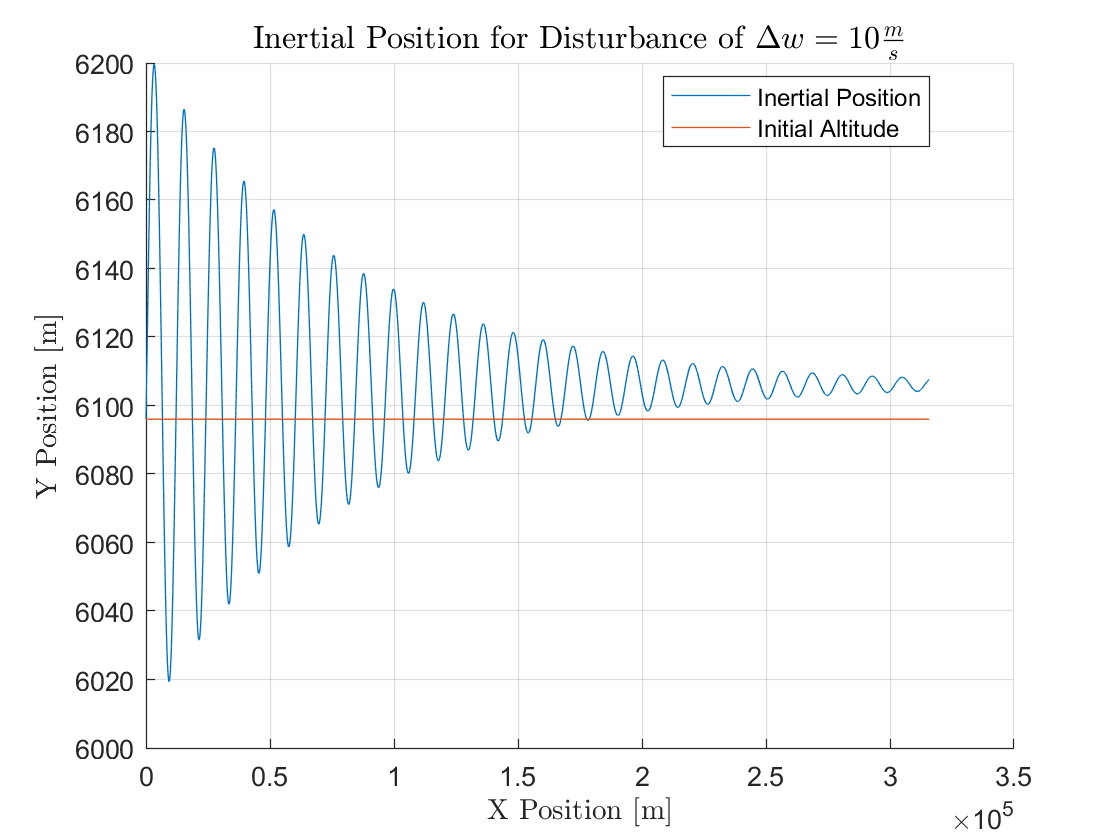

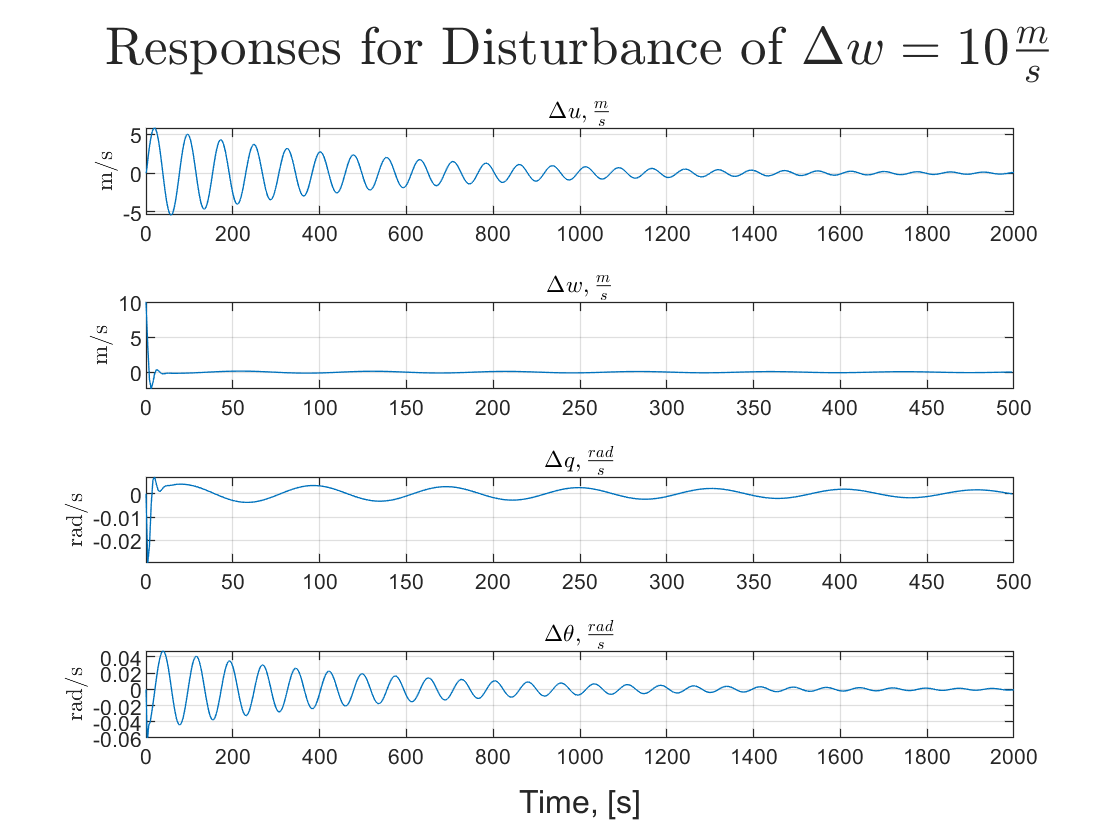

initialState(2) = 10; % Initial Delta w deviation of 10 [m/s]
[t, y] = ode45(@(t, y) AirplaneLinearized(t, y, A), tSpan, initialState);

plutter(t, y, 'Disturbance of $\Delta w = 10 \frac{m}{s}$')


t = 0;
y = 0;
initialState = initial;

### Part b.iii

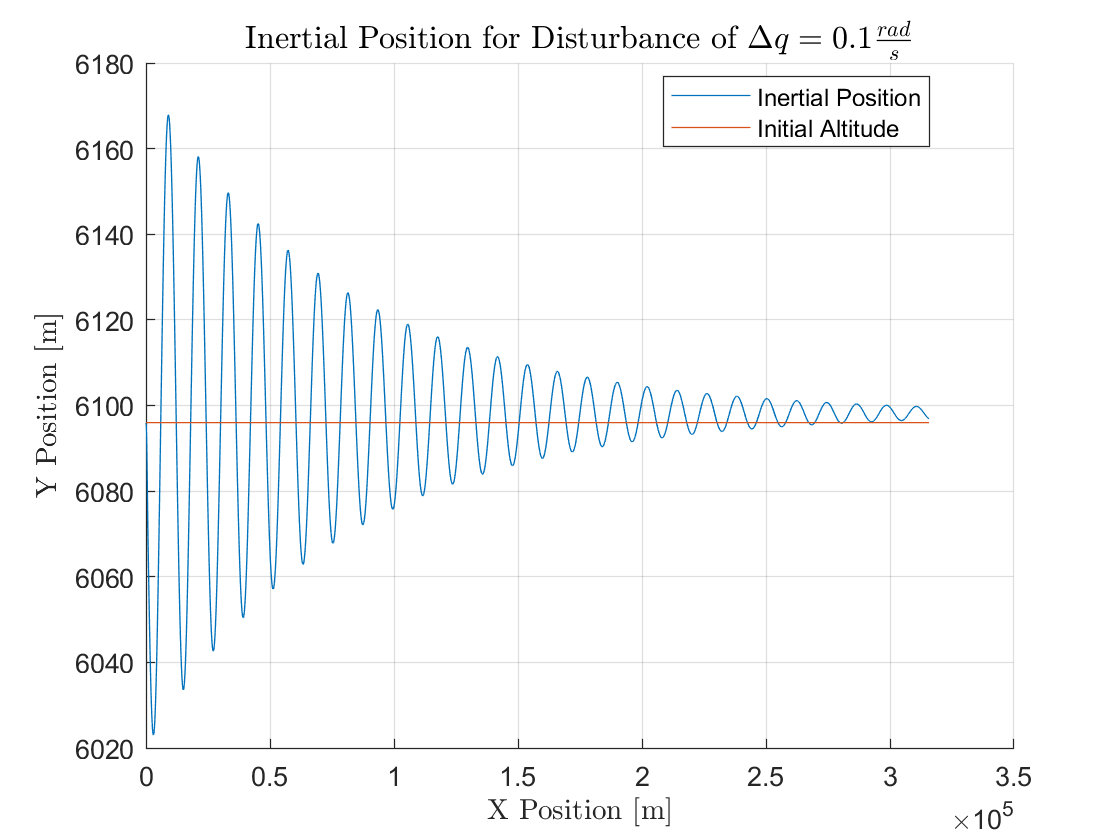

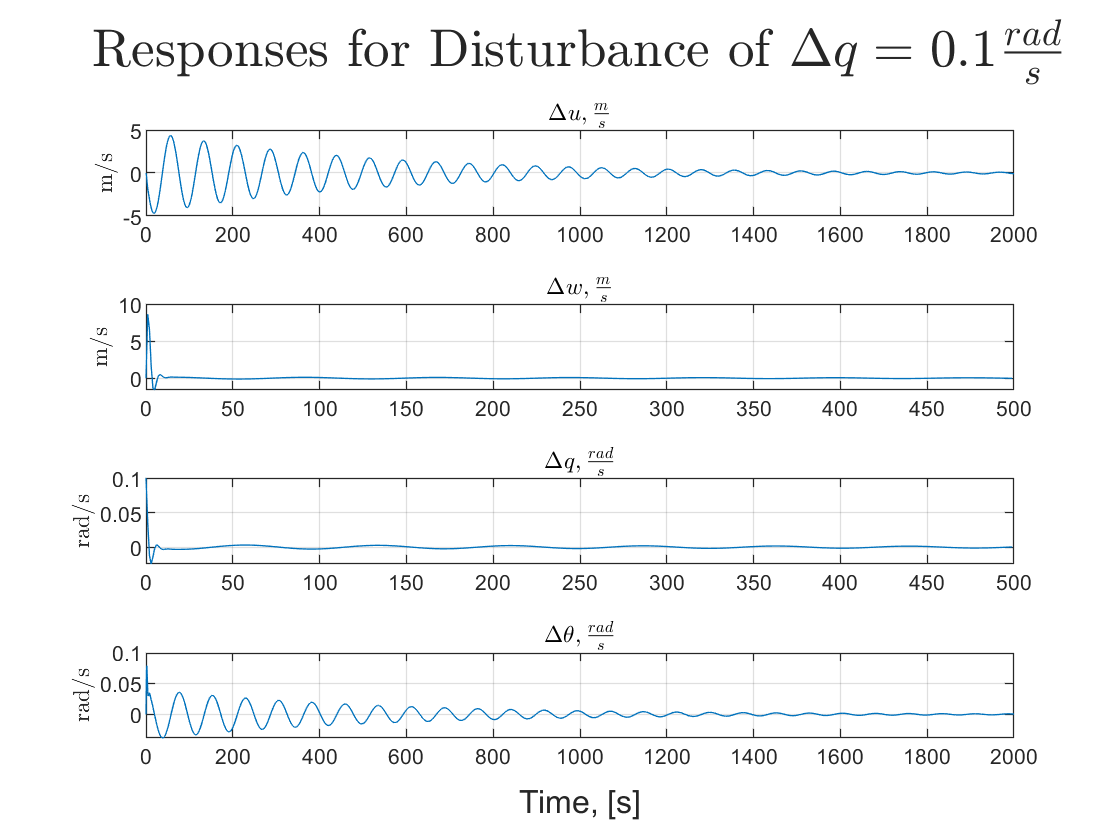

initialState(3) = 0.1; % Initial Delta q deviation of 0.1 [rad/s]
[t, y] = ode45(@(t, y) AirplaneLinearized(t, y, A), tSpan, initialState);

plutter(t, y, 'Disturbance of $\Delta q = 0.1 \frac{rad}{s}$')


t = 0;
y = 0;
initialState = initial;

### Part b.iv

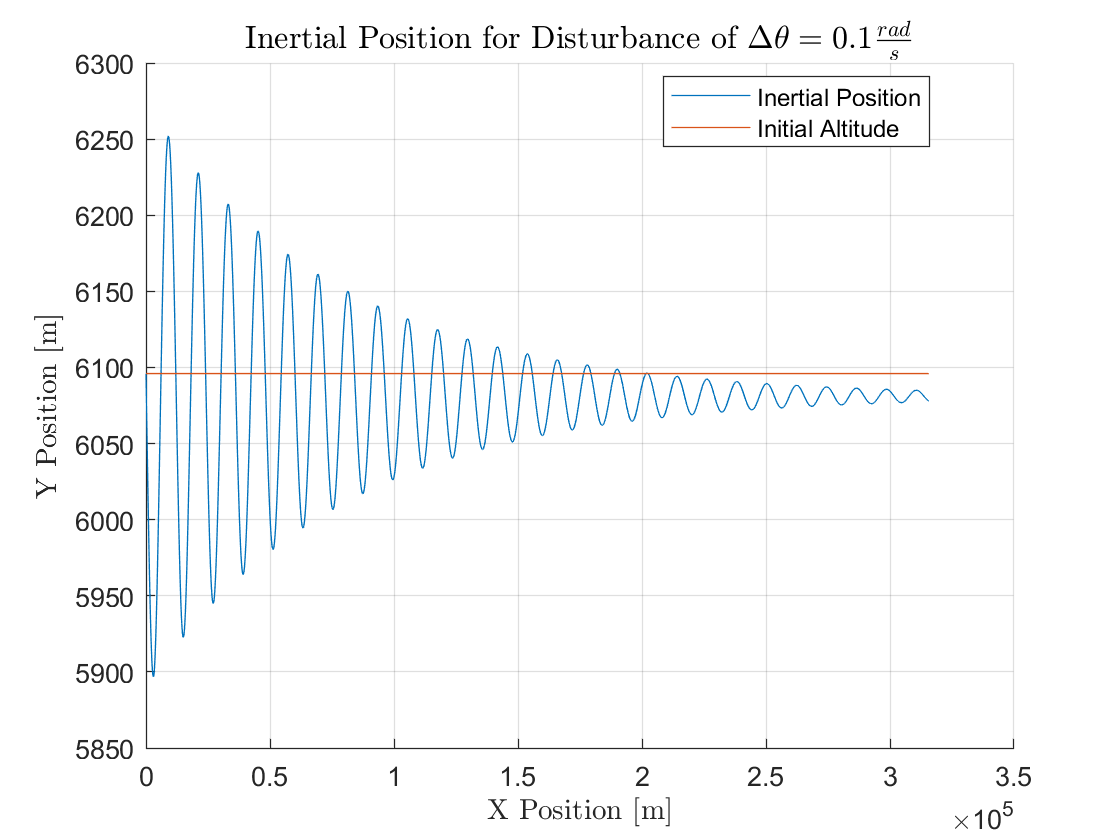

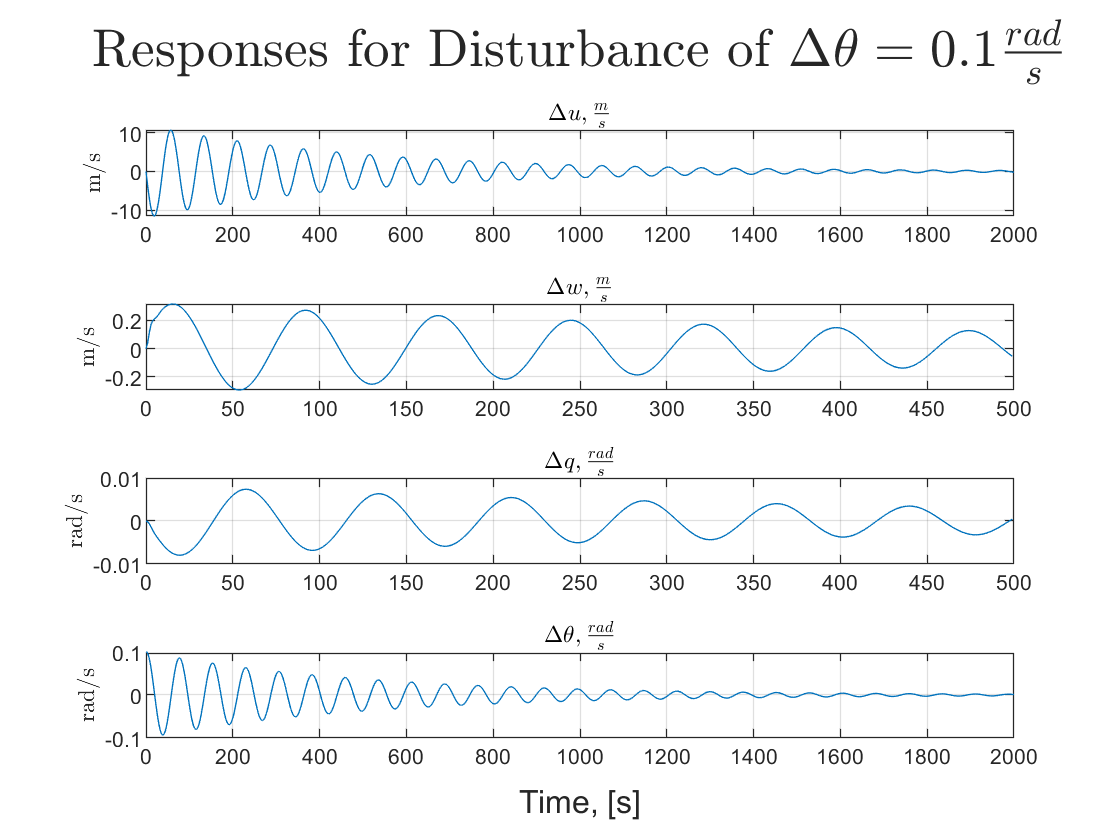

initialState(4) = 0.1; % Initial Delta theta deviation of 0.1 [rad/s]
[t, y] = ode45(@(t, y) AirplaneLinearized(t, y, A), tSpan, initialState);

plutter(t, y, 'Disturbance of $\Delta \theta = 0.1 \frac{rad}{s}$')


initialState = initial;

As we can see from the plots of responses to the disturbances, both a disturbance to $\Delta w$ and to $\Delta q$ are good at exciting the Short Period mode (the responses are damped very quickly, and have little residual oscillation).  On the other hand, disturbances to $\Delta u$ and to $\Delta \theta$ are good at exciting responses in the Phugoid mode.

Short Period Eigenvector for positive imaginary component:

disp(V(:,1))

   0.0301 + 0.0099i
   0.9995 + 0.0000i
  -0.0001 + 0.0059i
   0.0051 - 0.0024i



Phugoid Eigenvector for positive imaginary component:

disp(V(:,3))

   0.9996 + 0.0000i
  -0.0264 - 0.0074i
   0.0007 - 0.0000i
  -0.0006 - 0.0084i



Looking at the eigenvectors of the A matrix from question 4, we see that some disturbances are good at exciting responses from both modes, with one being more prevalent.  Going row by row:

Disturbances to $\Delta u$ excite both, but have more of an impact on the Phugoid mode.

Disturbances to $\Delta w$ excite both as well, but have more of an impact on the Short Period mode.

Disturbances to $\Delta q$ primarily excite the Short Period mode.

Disturbances to $\Delta \theta$ excites both modes as well.